# Toxic Conversations Dataset

## Setup

clc;
clear all;
close all;
rng(1634256, "twister");

addpath(genpath(fileparts(which(mfilename))));

## Load Data

% Import the data
rawData = parquetread("./datasets/toxic_conversations_50k/toxic_conversations_50k_all-mpnet-base-v2.parquet", "SelectedVariableNames", ["text", "label_text", "embedding"]);

rawData.label_text = categorical(rawData.label_text);

rawData(1:8, :)

ans = 8×3 table
                                                                                                                                                                                                                                                                                       text                                                                                                                                                                                                                                                                                       label_text       embedding   
    _________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________

groupcounts(rawData, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

    not toxic       46035        92.07 
    toxic            3965         7.93 


## Preperation

sampleSize = 1000;
contamination =0.2;
nonToxicIndices = find(rawData.label_text == "not toxic");
toxicIndices = find(rawData.label_text == "toxic");

numToxicSamples = round(contamination * sampleSize);
numNonToxicSamples = sampleSize - numToxicSamples;

toxicSampleIndices = datasample(toxicIndices, numToxicSamples, Replace=false);
nonToxicSampleIndices = datasample(nonToxicIndices, numNonToxicSamples, Replace=false);
data = rawData(sort(cat(1, toxicSampleIndices, nonToxicSampleIndices)),:);

clear numToxicSamples;
clear numNonToxicSamples;
clear toxicSampleIndices;
clear toxicIndices;
clear nonToxicIndices;
clear nonToxicSampleIndices;
clear rawData;

groupcounts(data, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

    not toxic        800          80   
    toxic            200          20   


unlabeledData = cell2mat(cellfun(@transpose,data.embedding, UniformOutput=false));
centredData = rZscores(unlabeledData);
labels = renamecats(data.label_text, {'not toxic' 'toxic'}, {'inlier' 'outlier'});

## Separability

Y = tsne(unlabeledData, Distance="cosine");

figure;
gscatter(Y(:,1),Y(:,2),labels);
title("t-SNE Embeddings");
clear Y;

separabilityindex(unlabeledData, labels, Distance="cosine")

ans = 0.7340

## Computation

alpha = 0.7;
% kModel = AutoRbfKernel(centredData);
kModel = AutoSphereRbfKernel(unlabeledData);

AutoSphereRbfKernel: Sigma = 1.01267249391019


poc = kMRCD(kModel); 
% solution = poc.runAlgorithm(centredData, alpha);
solution = poc.runAlgorithm(unlabeledData, alpha);

Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SSCM


## Evaluation

hSubset = data(solution.hsubsetIndices, :);

groupcounts(hSubset, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

    not toxic        560          80   
    toxic            140          20   


outliers = data(solution.flaggedOutlierIndices, :);

groupcounts(outliers, "label_text")

ans = 2×3 table
    label_text    GroupCount    Percent
    __________    __________    _______

    not toxic        240          80   
    toxic             60          20   


### Confusion Matrix

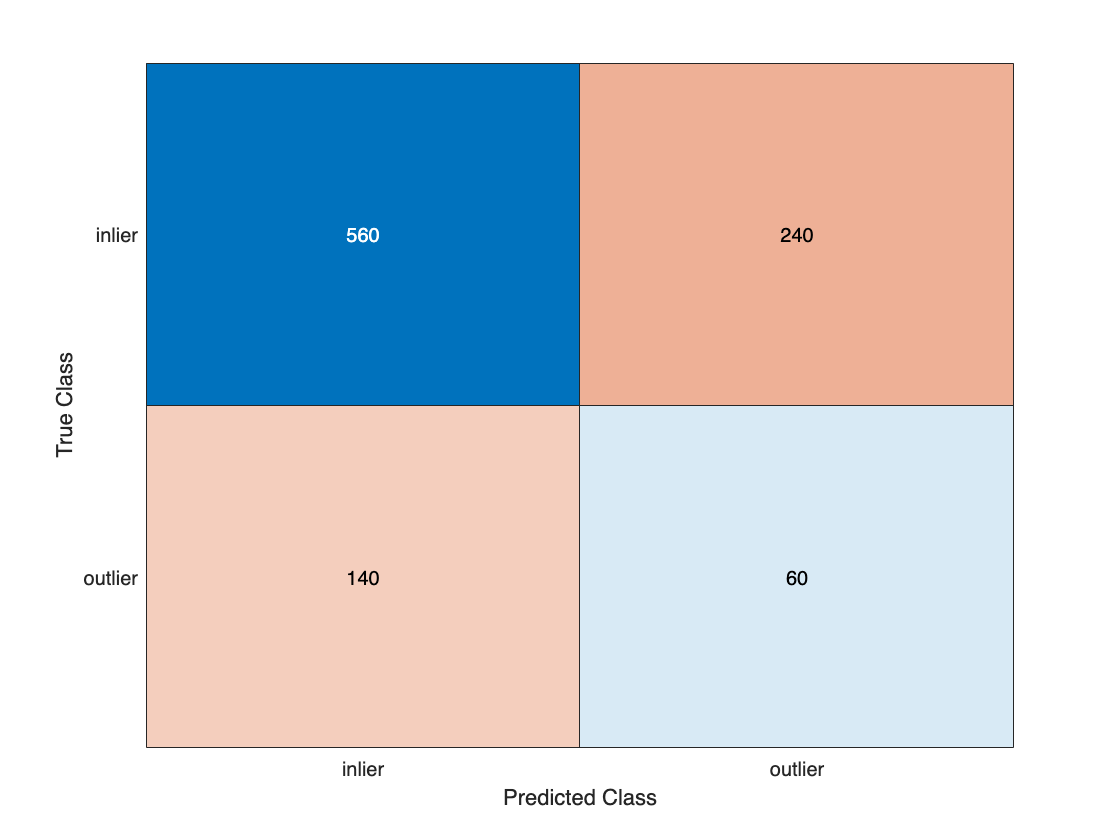

grouphat = categorical(repmat("inlier", size(labels)), categories(labels));
grouphat(solution.flaggedOutlierIndices) = "outlier";

cm = confusionmat(labels,grouphat);
figure;
confusionchart(cm, categories(labels));

struct2table(confusionstats(cm))

ans = 1×5 table
    accuracy    precision    sensitivity    specificity    f1Score
    ________    _________    ___________    ___________    _______

      0.62         0.2           0.3            0.7         0.24  


### Mahalanobis Distances

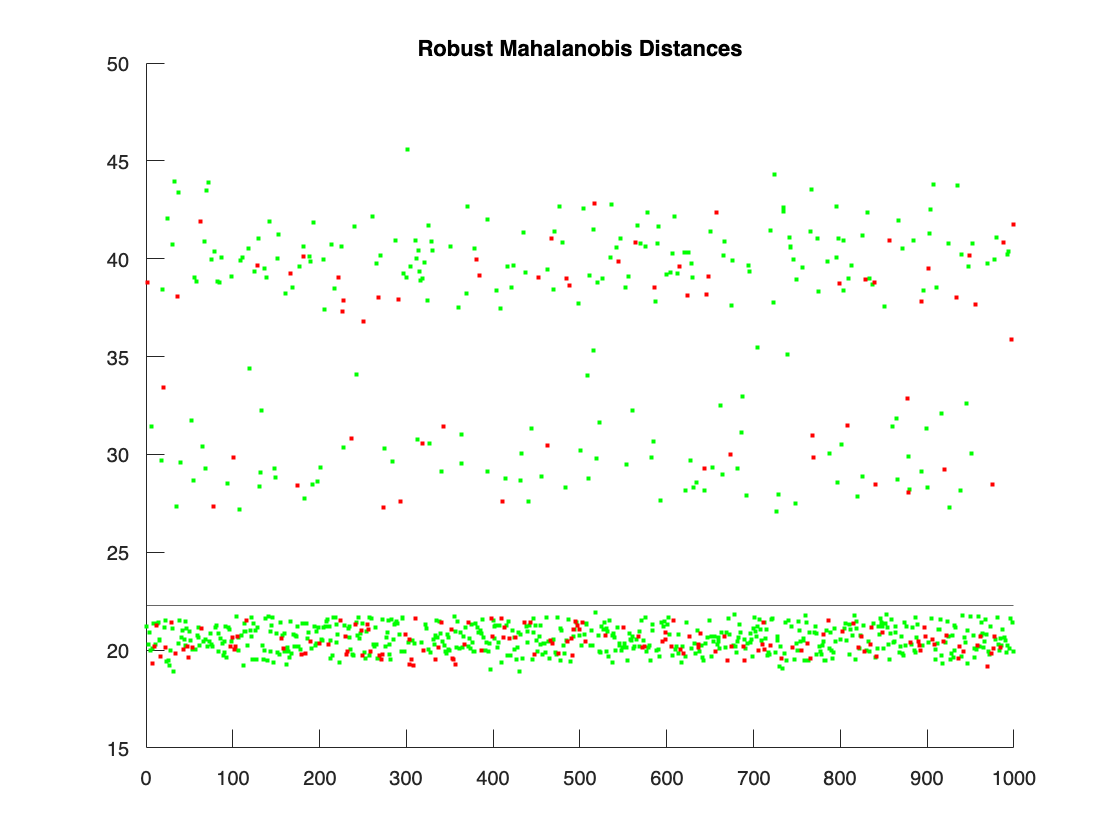

figure;
mahalchart(labels, solution.rd, solution.cutoff);

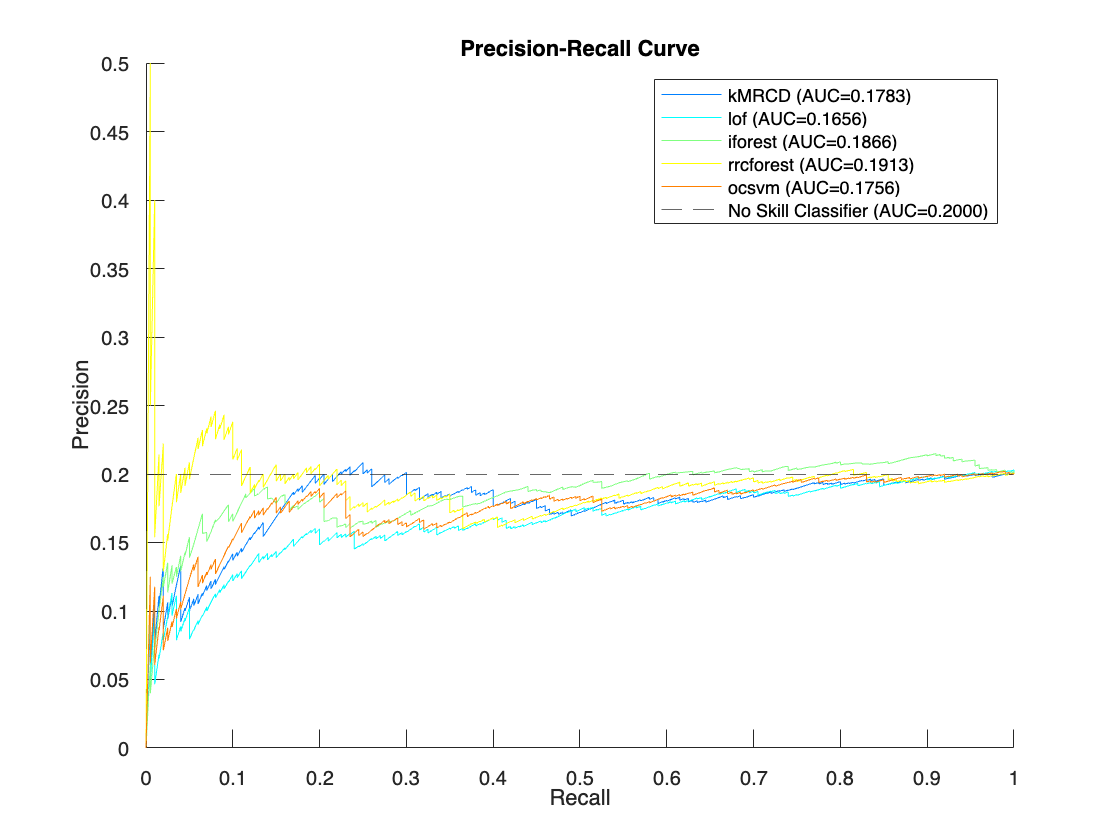

ans = 5×6 table
                 accuracy    precision    sensitivity    specificity    f1Score     aucpr 
                 ________    _________    ___________    ___________    _______    _______

    kMRCD          0.62           0.2          0.3             0.7        0.24     0.17828
    lof           0.594       0.15667        0.235         0.68375       0.188     0.16556
    iforest       0.601       0.16722         0.25         0.68875      0.2004     0.18622
    rrcforest     0.602          0.17        0.255         0.68875       0.204     0.18098
    ocsvm         0.594       0.15667        0.235         0.68375       0.188     0.17221


evaluation(unlabeledData, labels, alpha, solution)

% objectiveplot(poc, centredData);
objectiveplot(poc, unlabeledData);

Convergence at iteration 1, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 1, SSCM
-> Best estimator is SSCM
